%% SISTEMA DE CONTROL AVANZADO MYCOBOT
% Integra: ROS 2 (Hardware) + URDF (Modelo) + Planificación Continua

%% 1. Inicialización del Sistema
clear; clc;


% A) Conectar Hardware
try
    robot_hw = erobotics_interface();
    pause(1); % Dar tiempo a recibir el primer mensaje de /joint_states
catch
    warning('ROS 2 no detectado. Modo SIMULACIÓN.');
    robot_hw = [];
end

--- Iniciando Hardware MyCobot ---
 [tf_monitor] Listo para visualizar.
 ¡CONEXIÓN ESTABLECIDA con el Robot!



% B) Cargar Modelo
robot_model = MyCobotModel()

robot_model =   MyCobotModel with properties:

        RobotTree: [1×1 rigidBodyTree]
         IKSolver: [1×1 inverseKinematics]
       HomeConfig: [0 0 0 0 0 0]
      EndEffector: 'joint6_flange'
             Node: [1×1 ros2node]
         JointSub: [1×1 ros2subscriber]
    CurrentJoints: []


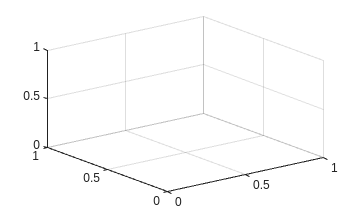


% C) Iniciar Planificador
planner = TrajectoryPlanner(robot_model);

Sincronizando con el robot real...


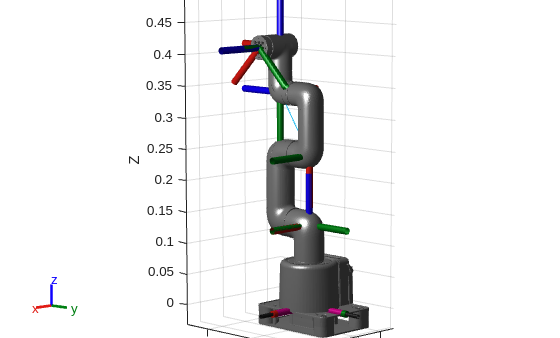


% D) Visualización Inicial (Estado Real)
if ~isempty(robot_hw)
    disp('Sincronizando con el robot real...');
    planner.sincronizarConHardware();
end


disp('Sistema listo.');

Sistema listo.


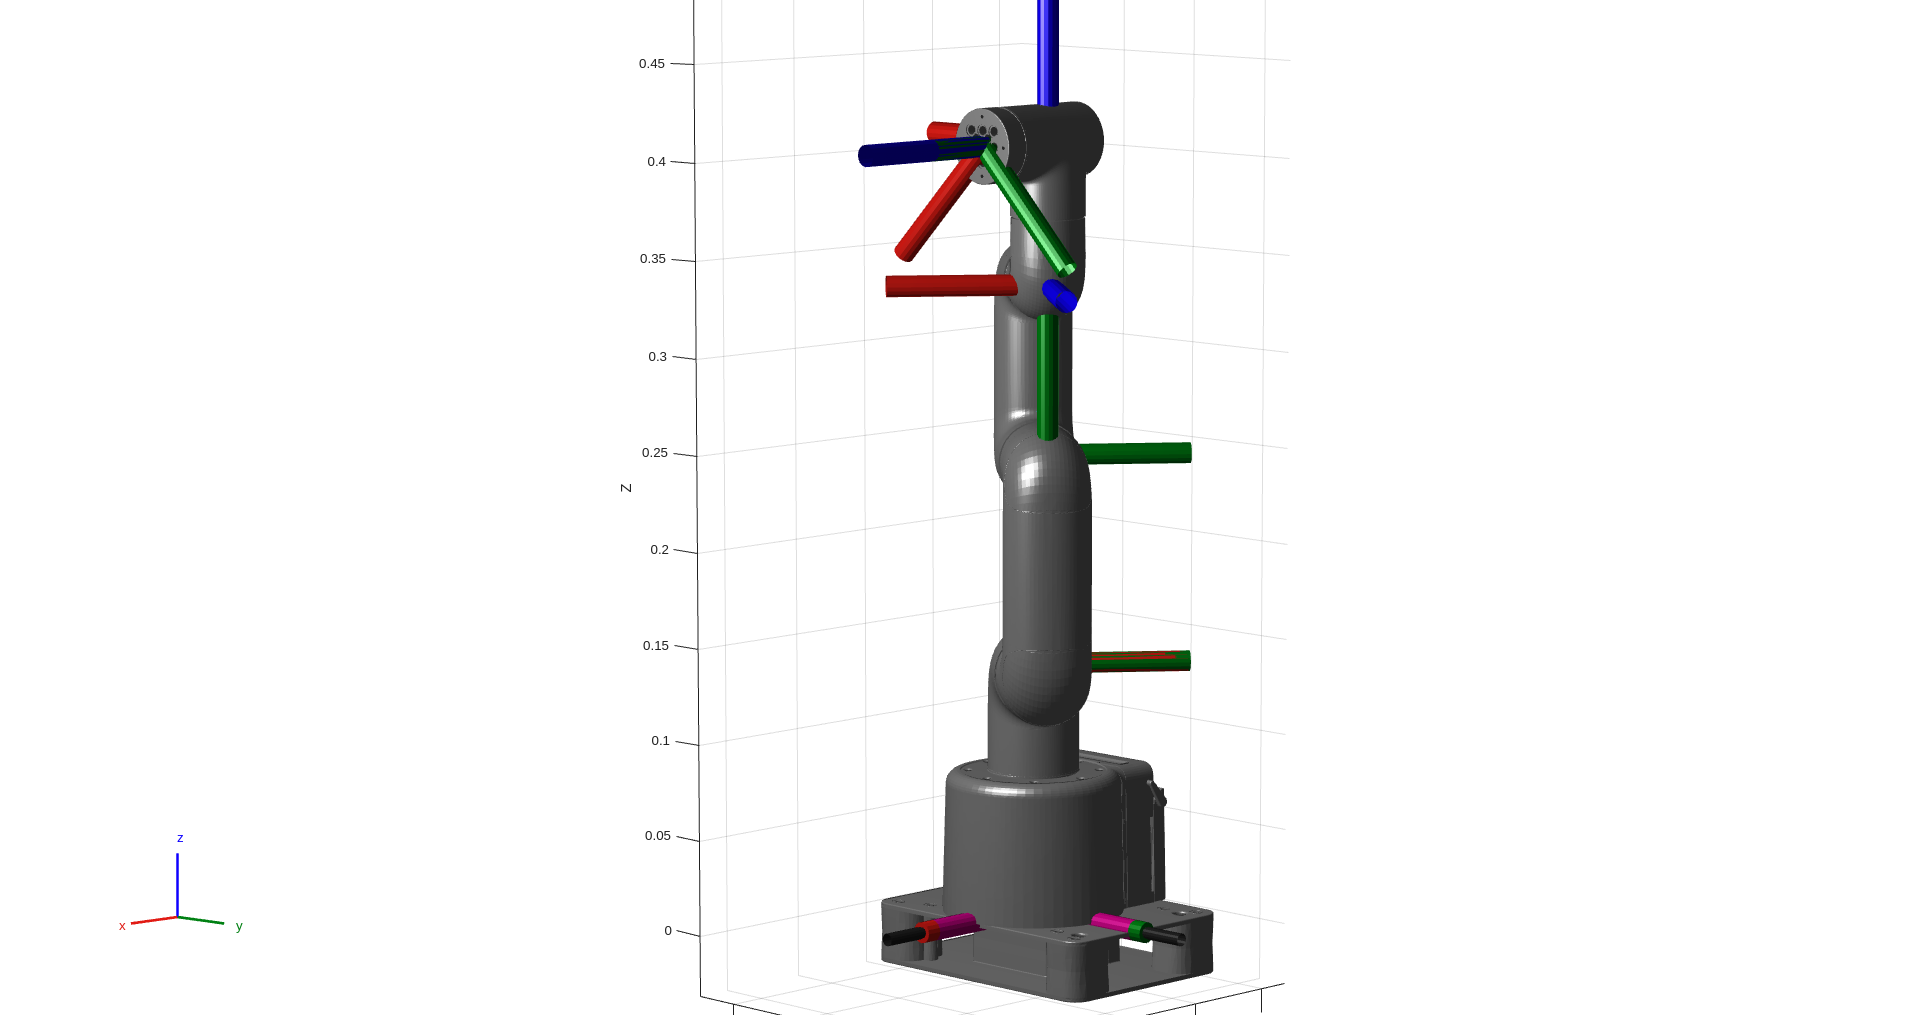

qMatrix =     0.4300    0.1700   -0.4300    0.2600    0.1700   44.7300
    3.4250   -0.0001   -0.0000    0.0005   -2.8889   44.7600
    7.6856    0.0026   -0.0060    0.0043   -7.2136   44.7898
   14.4545    0.0064   -0.0146    0.0094  -14.0468   44.8196
   26.3349    0.0125   -0.0281    0.0173  -25.9923   44.8492
   48.8902   -0.0009   -0.0000    0.0038  -48.6155   44.8778
   84.6558   -0.0077    0.0000    0.0304  -84.4546   44.8875
  115.1642    0.0020   -0.0000   -0.0077 -115.0356   44.9453
  131.8598    0.0013   -0.0000   -0.0051 -131.7993   44.9730
  140.8811    0.0012    0.0000   -0.0046 -140.8864   45.0023



%% 2. Control Cartesiano (Desde posición actual)
% El robot partirá de donde esté ahora mismo (leído por sensores)
% hacia la nueva coordenada.

x = 0.07; 
y = 0.03; 
z = 0.42;

% Orientación (Radianes)
roll = -pi/2; pitch = pi/4; yaw = -pi/2;

tiempo = 4.0; 

qMatrix = planner.planificarCartesiano(x, y, z, roll, pitch, yaw, tiempo)

% Ejecutar la trayectoria planificada
robot_hw.ejecutarTrayectoria(qMatrix, tiempo);

 Enviando trayectoria... Destino: [140.9    0.0    0.0   -0.0 -140.9   45.0]


robot_hw.irAHome();

 Enviando trayectoria... Destino: [0.0  0.0  0.0  0.0  0.0 45.0]


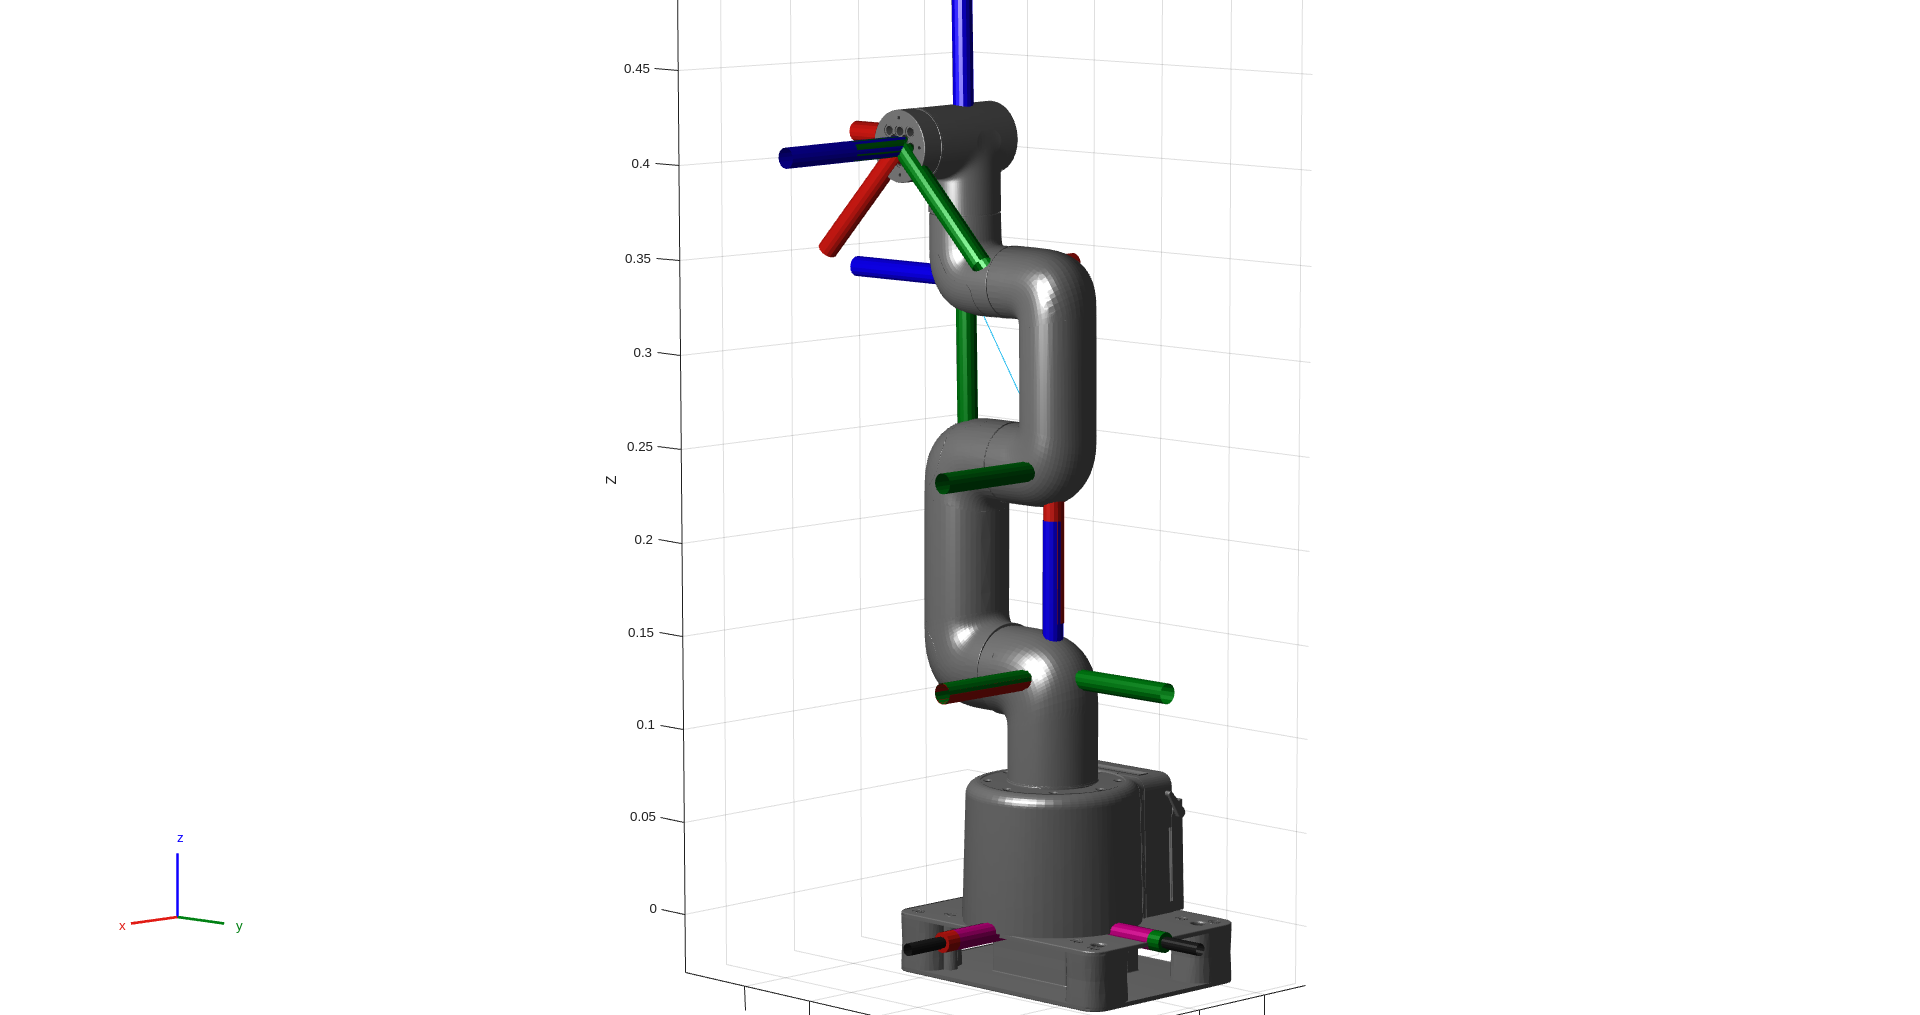

planner.sincronizarConHardware();